clear all
load ARTEMIS.mat;

prob=optimproblem; %initializzi il problema
start=60;%Definisci l'istante iniziale
N=10; %Time horizon

%Estrai i sottovettori
speed=ARTEMIS(1,start:start+N-1);
acceleration=ARTEMIS(2,start:start+N-1);
gear=ARTEMIS(3,start:start+N-1);

%Definisci l'handle della funzione di update dello stato
StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);

SOC_lowerbound=0.20; %Bounds del SOC
SOC_upperbound=0.80;


%Definisci le variabili di ottimizzazione, SOC e mf saranno completamente
%vincolate ad u, ma sono utili per la funzione di costo, si possono evitare?
u=optimvar('u',N,"LowerBound",-1,"UpperBound",1);
SOC=optimvar('SOC',N,"LowerBound",SOC_lowerbound,"UpperBound",SOC_upperbound);
mf=optimvar('mf',N);

%Definisci i constraint di uguaglianza per vincolare SOC e mf
eq_constraints=optimconstr(N,2);

%i+1 o i-1?
for i=2:N
    [out1,out2]=fcn2optimexpr(StateUpdate,u(i-1),SOC(i-1),i);
    eq_constraints(i,1)= mf(i)==out1;
    eq_constraints(i,2)= SOC(i)==out2;
end

prob.Constraints.equality=eq_constraints;

%Definisci la cost function e gli stati iniziali, la mf deve essere pesata
%molto di più perché è molti ordini di grandezza più bassi su un orizzonte
%così piccolo
a=10000;
b=10;
prob.Objective=a*sum(mf.^2) + b*sum((0.55-SOC).^2);

%Inizializzi le ipotesi iniziali
initialGuess.u=-ones(N,1);

initial_SOC=0.55*ones(N,1);
initial_mf=zeros(N,1);
for i=2:N
    [initial_mf(i),initial_SOC(i)]=StateUpdate(initialGuess.u(i),initial_SOC(i),i);
end
initialGuess.SOC=initial_SOC;
initialGuess.mf=initial_mf;

show(prob)


  OptimizationProblem : 

	Solve for:
       SOC, mf, u

	minimize :
       ((10000 .* sum(mf.^2)) + (10 .* sum((0.55 - SOC).^2)))


	subject to equality:
       arg_LHS == arg_RHS

       where:

             arg1 = zeros(10, 2);
             arg1(2) = mf(2);
             arg1(12) = SOC(2);
             arg1(3) = mf(3);
             arg1(13) = SOC(3);
             arg1(4) = mf(4);
             arg1(14) = SOC(4);
             arg1(5) = mf(5);
             arg1(15) = SOC(5);
             arg1(6) = mf(6);
             arg1(16) = SOC(6);
             arg1(7) = mf(7);
             arg1(17) = SOC(7);
             arg1(8) = mf(8);
             arg1(18) = SOC(8);
             arg1(9) = mf(9);
             arg1(19) = SOC(9);
             arg1(10) = mf(10);
             arg1(20) = SOC(10);
             arg_LHS = reshape(arg1, [10, 2]);
             arg1 = zeros(10, 

%opts=optimoptions("lsqnonlin","MaxIterations",1e5,"MaxFunctionEvaluations",1e5);
tic
sol=solve(prob,initialGuess)

Solving problem using lsqnonlin.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    SOC: [10×1 double]
     mf: [10×1 double]
      u: [10×1 double]


toc

Elapsed time is 14.761748 seconds.


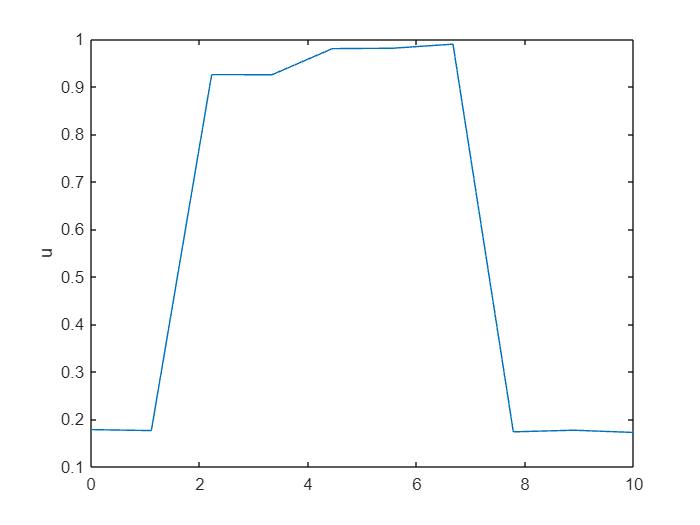

t=linspace(0,N,N);
plot(t,sol.u)
ylabel('u')

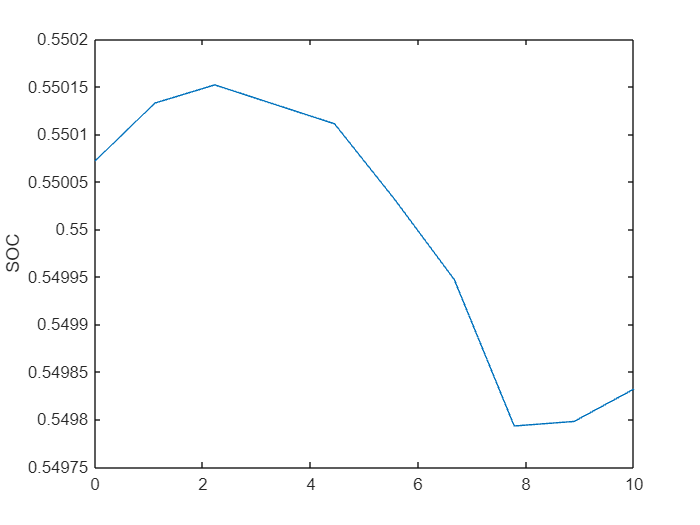

plot(t,sol.SOC)
ylabel('SOC')

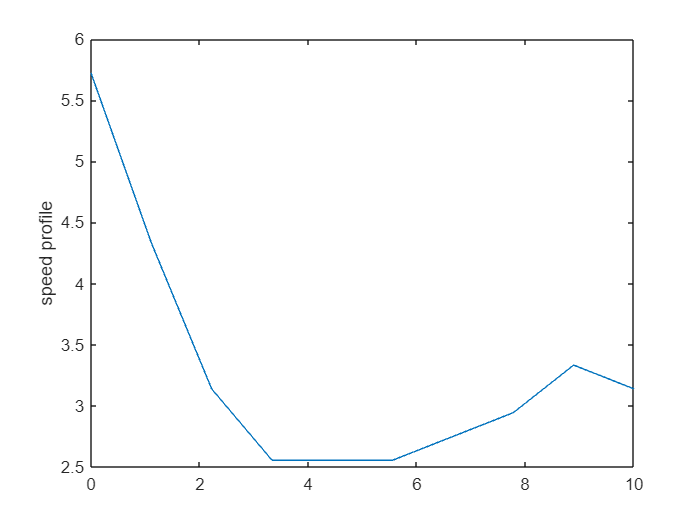

% plot(sol.mf)
% ylabel('mf')
plot(t,speed(1:N))
ylabel('speed profile')

sum(sol.mf.^2)

ans = 1.8472e-10

sum((0.55-sol.SOC).^2)

ans = 1.9097e-07